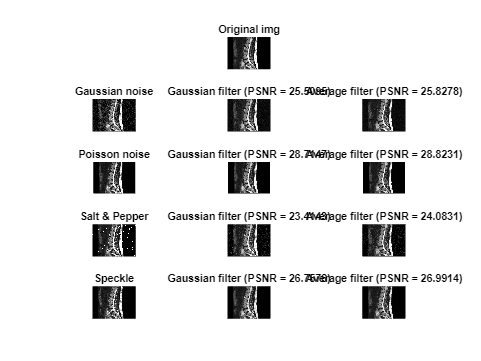


im = imread("spine.jpg");
im1 = rgb2gray(im);

%adding noise
gau = imnoise(im1,"gaussian");
pois = imnoise(im1,"poisson");
sp = imnoise(im1,"salt & pepper");
spec = imnoise(im1,"speckle");

%filters
avg = [1/9 1/9 1/9;1/9 1/9 1/9;1/9 1/9 1/9];
gau_fil = [1/16 1/8 1/16;1/8 1/4 1/8;1/16 1/8 1/16];

%original image
subplot(532);
imshow(im1);title("Original img");

%gaussian
subplot(534);
imshow(gau);title("Gaussian noise");
subplot(535);
a = uint8(convolution(double(gau),gau_fil));
imshow(a);title(sprintf("Gaussian filter (PSNR = %3.4f)",psnr(a,im1)));
subplot(536);
b = uint8(convolution(double(gau),avg));
imshow(b);title(sprintf("Average filter (PSNR = %3.4f)",psnr(b,im1)));

%poisson
subplot(537);
imshow(pois);title("Poisson noise");
subplot(538);
c = uint8(convolution(double(pois),gau_fil));
imshow(c);title(sprintf("Gaussian filter (PSNR = %3.4f)",psnr(c,im1)));
subplot(539);
d = uint8(convolution(double(pois),avg));
imshow(d);title(sprintf("Average filter (PSNR = %3.4f)",psnr(d,im1)));

%salt & pepper
subplot(5,3,10);
imshow(sp);title("Salt & Pepper");
subplot(5,3,11);
e = uint8(convolution(double(sp),gau_fil));
imshow(e);title(sprintf("Gaussian filter (PSNR = %3.4f)",psnr(e,im1)));
subplot(5,3,12);
f = uint8(convolution(double(sp),avg));
imshow(f);title(sprintf("Average filter (PSNR = %3.4f)",psnr(f,im1)));

%speckle
subplot(5,3,13);
imshow(spec);title("Speckle");
subplot(5,3,14);
g = uint8(convolution(double(spec),gau_fil));
imshow(g);title(sprintf("Gaussian filter (PSNR = %3.4f)",psnr(g,im1)));
subplot(5,3,15);
h = uint8(convolution(double(spec),avg));
imshow(h);title(sprintf("Average filter (PSNR = %3.4f)",psnr(h,im1)));

function y = convolution(a,b)
[r,c] = size(a);
y = zeros(r,c);
for i = 1:r-2
    for j = 1:c-2
       y(i,j) = sum(sum(a(i:i+2,j:j+2).*b));
    end
end
end